In this notebook, we intend to check if there is any errors in the transformation of real data. To do so, we take the control cmd on the motor levels from the robots, and use it to make a simulation using the digital twin. We will compare the simulated trajectory (both cmd and response) to the measured values. If there is no systematic error, then, the transformation of scale is done correctly.

%% Load the simulation model, define parameters.

clear; clc; close all;

addpath('../digital_model_complete/')
addpath('../digital_model_kinematics/')

% Define parameters of the simulink model.
mdl_name = 'main3_armpi_fpv.slx';
load_system(mdl_name);

joint1_damping = 0;
joint2_damping = 0;
damp_pince = 1000;

# Process the real data

% Define the real dataset used for the checking.
% Get all the subfolders in the orginal dataset.
base_dict = 'collection/label_0/';

% Constants
seq_length = 1000; % Length of one sequence.
sequence_time = 10; % The sequence corresponds to 10 seconds.
extract_seq = 1; % Index of the trajectory that needs extraction.

% Read the data Tables.
[cmd, duration, position] = read_preprocess_data(base_dict);

% Prepare initial values.
input_motor_commands = cell(1, 5); % Commands.
joint_cmds_real = cell(1, 5); % Commond, transfered scale.
joint_resps_real = cell(1, 5); % Responses.

% Get the data for the current run.
[cmd_i, duration_i, position_i] = extract_run_i(cmd, duration, position, extract_seq, sequence_time);

for j = 1:5
    motor_idx = ['motor_' num2str(7-j)];
    [reference_position, response_position] = generate_seq_by_interpl(cmd_i, duration_i, position_i, motor_idx, seq_length, sequence_time);
    
    % Post processing.
    input_motor_commands{j} = timeseries(reference_position(:, 2), reference_position(:, 1));

    % Transform the scales of the motor positions.
    % Get the control command in the correct format.
    j_cmd = transform_cmd_format(input_motor_commands{j});
    joint_cmds_real{j} = j_cmd;

    % Transform the scale of the response.
    j_resp = timeseries(response_position(:, 2), response_position(:, 1));
    joint_resps_real{j} = transform_cmd_format(j_resp);
end

% Apply the virtual sensor to measure the 3d coordinates.
% For the command.
traj_cmd_real = virtual_sensor(joint_cmds_real);

% For the response
traj_resp_real = virtual_sensor(joint_resps_real);

# Simulate for the same command

failure_type = 0;
visualization = 0;
[joint_cmds_sim, joint_resps_sim, traj_cmd_sim, traj_resp_sim] = run_simulation(input_motor_commands, failure_type, mdl_name, visualization);

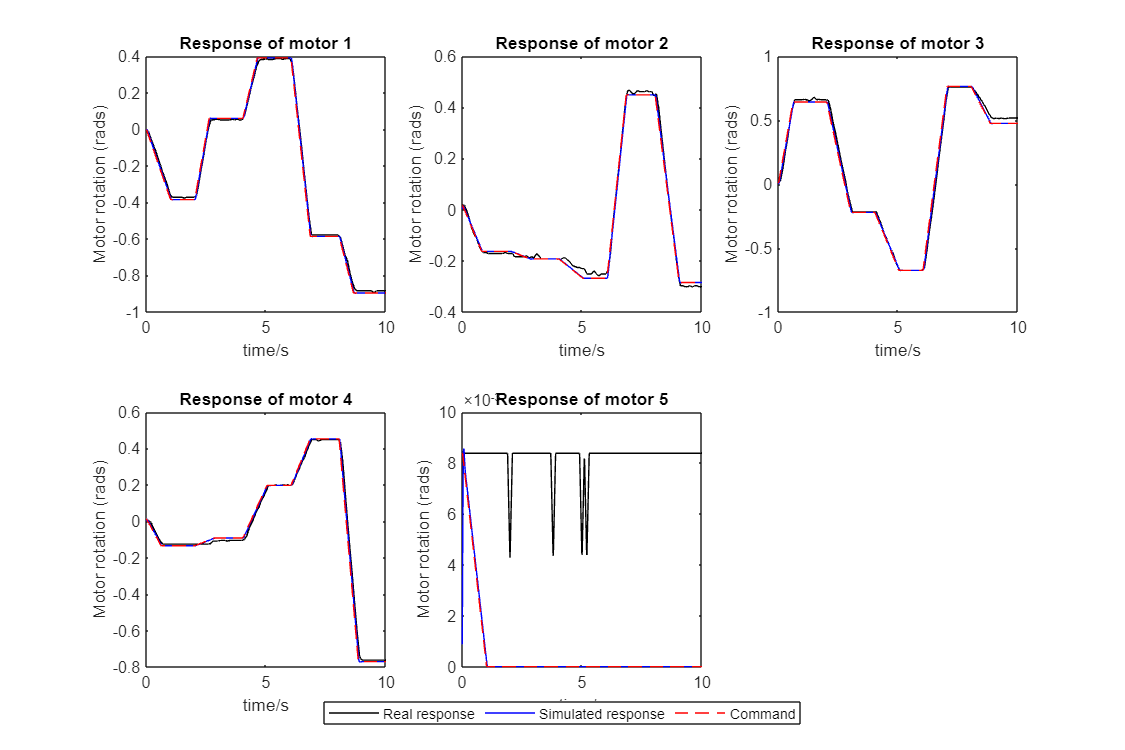

% Create a Figure of the real response V.S. simulated response for each motor.
f1 = figure;
f1.Position = [10 10 900 600];

for i = 1:5
    subplot(2, 3, i);
    plot(joint_resps_real{i}, '-k');
    hold on
    plot(joint_resps_sim{i}, '-b');
    hold on
    plot(joint_cmds_real{i}, '--r')
    xlabel('time/s')
    ylabel('Motor rotation (rads)');
    title(['Response of motor ' num2str(i)])
end
legend('Real response', 'Simulated response', 'Command', 'Position', [0.5 0.05 0 0], 'Orientation', 'horizontal')

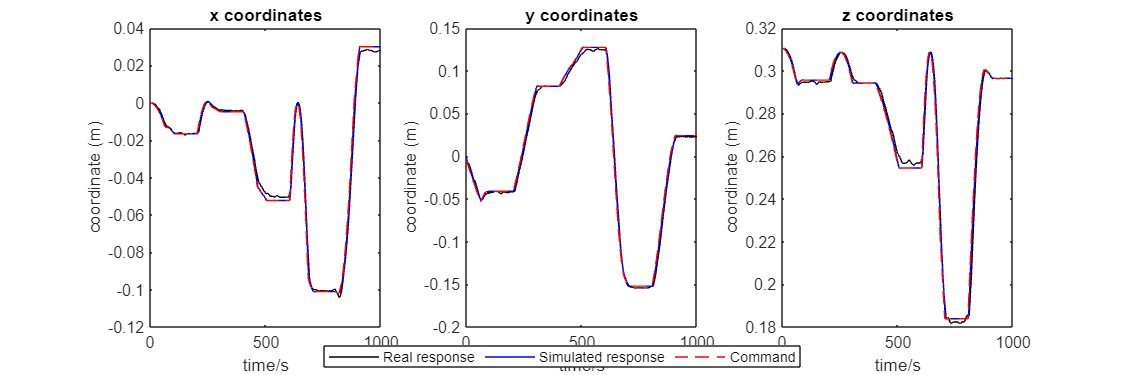

% Create a Figure of the real response V.S. simulated response for each motor.
f2 = figure;
f2.Position = [10 10 900 300];
titles = {'x coordinates', 'y coordinates', 'z coordinates'};
for i = 1:3
    subplot(1, 3, i);
    plot(traj_resp_real(:, i), '-k');
    hold on
    plot(traj_resp_sim(:, i), '-b');
    hold on
    plot(traj_cmd_real(:, i), '--r')
    xlabel('time/s')
    ylabel('coordinate (m)');
    title(titles{i})
end
legend('Real response', 'Simulated response', 'Command', 'Position', [0.5 0.05 0 0], 'Orientation', 'horizontal')

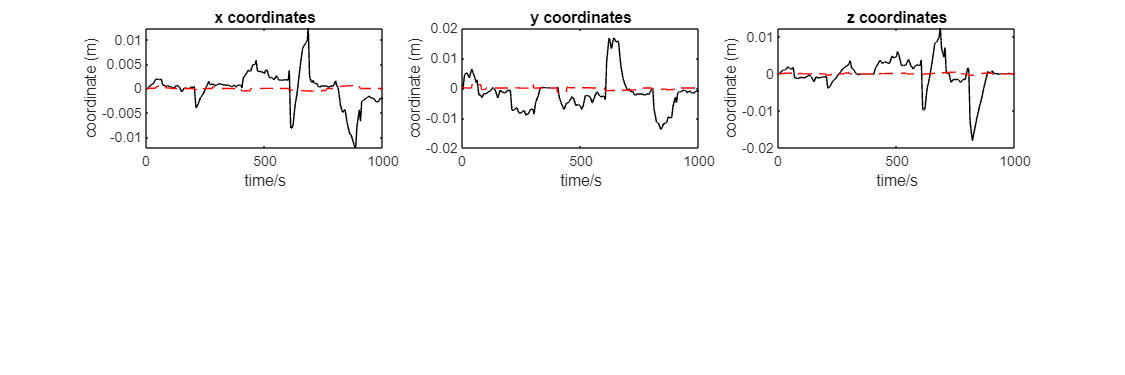

% Create a Figure of the residuals on x, y, z, both real dataset and
% simulation dataset.

training_data_name = 'all_training_dataset.mat';
training_data_path = '../RobotPdMDataset';
datasetPath = fullfile(training_data_path, training_data_name);
load(datasetPath, 'X', 'y');
y = categorical(y);

example_sim_dataset = X(y=='Healthy');
example_sim_dataset = example_sim_dataset{1};

residual_real = traj_resp_real-traj_cmd_real;
residual_simulation = example_sim_dataset(:, 4:6) - example_sim_dataset(:, 1:3);

f3 = figure;
f3.Position = [10 10 900 300];
titles = {'x coordinates', 'y coordinates', 'z coordinates'};
for i = 1:3
    subplot(2, 3, i);
    plot(residual_real(:, i), '-k');
    hold on
    plot(residual_simulation(:, i), '--r');
    xlabel('time/s')
    ylabel('coordinate (m)');
    title(titles{i})
end

# Supporting function

function [cmd, duration, position] = read_preprocess_data(path_label)
% This function read the three csv files obtained from the robot.
% Then, it aligns the time scale by in the column 'time_since_start'.
% Returns:
% - cmd, duration, position: Table object with aligned time scales.

% Read the data Tables.
cmd = readtable(fullfile(path_label, 'trajectory_monitoring_cmd.csv')); % Commands
duration = readtable(fullfile(path_label, 'trajectory_monitoring_cmd_duration.csv')); % Duration of each movement
position = readtable(fullfile(path_label, 'trajectory_monitoring_position.csv')); % Monitored positions.

% Get the time origin.
timestamp_cmd = cmd.timestamp;
timestamp_duration = duration.timestamp;
timestamp_position = position.timestamp;
starting_time = min([min(timestamp_cmd), min(timestamp_duration), min(timestamp_position)]);

% Subtract the starting time.
timestamp_cmd = timestamp_cmd - starting_time;
timestamp_duration = timestamp_duration - starting_time;
timestamp_position = timestamp_position - starting_time;

% Save to column 'time_since_start'
cmd.time_since_start = timestamp_cmd;
duration.time_since_start = timestamp_duration;
position.time_since_start = timestamp_position;

end


function [cmd_i, duration_i, position_i] = extract_run_i(cmd, duration, position, i, sequence_time)
% This function extract the corresponding data for the ith run, from the
% original data of cmd, duration and position.

% Extract current command and duration.
cmd_i = cmd(((i-1)*7+2):((i-1)*7+6), :);
duration_i = duration(((i-1)*7+2):((i-1)*7+6), :);

% Get the moment when the first control command was sent in each
% sequence. This is 2+(i-1)*7th element in timestamp_cmd.
command_starting_time = cmd{2+(i-1)*7, 'time_since_start'};

% Find indices of elements in timestamp_position that are smaller than command_starting_time
timestamp_position = position.time_since_start;
valid_indices = find(timestamp_position < command_starting_time);
valid_elements = timestamp_position(valid_indices);
[sequence_starting_time, relative_index] = max(valid_elements);
sequence_starting_time_index = valid_indices(relative_index);

% Find the end of this sequence.
sequence_ending_time = sequence_starting_time + sequence_time;
valid_indices = find(timestamp_position > sequence_ending_time);
valid_elements = timestamp_position(valid_indices);
[~, relative_index] = min(valid_elements);
sequence_ending_time_index = valid_indices(relative_index);

% Extract the current position.
position_i = position(sequence_starting_time_index:sequence_ending_time_index, :);

end


function [reference_positions, response_positions] = generate_seq_by_interpl(cmd, motor_cmd_duration, position, motor, seq_length, seq_time)
% Ths function takes as input the data obtained from the robot, and create
% a sequence following the format of the Matlab training script by
% interpolation.
% Inputs:
% - cmd, duration, position: The three Table objects containing the
% original cata. After aligning the time scale.
% - motor: int, which motor needs to be extracted.
% - seq_length: The length of the new sequence after the interpolation.
% - Returns:
% - reference_positions, response_positions: Timeseries object of the
% command and response for a given motor.

% Get the command and duration data for the given motor.
motor_command = cmd.(motor);
motor_cmd_duration = motor_cmd_duration.(motor);

% Find the staring index in the position.
cmd_send_time = cmd.time_since_start; % Time instants when the control cmd is send.
start_index_pos = find(position.time_since_start < cmd_send_time(1), 1, 'last'); % Right before the control cmd is sent.
% Mark the starting position of the position Table: Starting from the prev
% moment when control cmd was sent.
if isempty(start_index_pos)
    error('Please start monitoring before the control command is sent!');
else
    starting_position = position{start_index_pos, motor}; % The position before cmd is sent.
    cmd_send_time = cmd_send_time - position.time_since_start(1); % Reset the time scale.
    resp_measure_time = position.time_since_start - position.time_since_start(1);
end

% Get a serires points for interpolation.
% Format: Each row: [time, position] for the control cmd sequence.
points = zeros(2*length(motor_command)+1, 2); % Initial values.
points(1, :) = [cmd_send_time(1), starting_position]; % Initial position.
% First command: A linear increase to command(1), in duration(1) time.
points(2, :) = [cmd_send_time(1)+motor_cmd_duration(1)/1000, motor_command(1)];
% Add the other command.
for idx = 2:length(motor_command)
    points((idx-1)*2+1, :) = [cmd_send_time(idx), motor_command(idx-1)];  %this places the target point
    points((idx-1)*2+2, :) = [cmd_send_time(idx)+motor_cmd_duration(idx)/1000, motor_command(idx)]; %this creates an articial target representing the end of the plateau
end
% Add the last point: Hold the position to the current value until the end
% of the position sequence.
points(end, :) = [resp_measure_time(end), motor_command(end)];
if points(end, 1) < points(end-1, 1)
    points = points(1:end-1, :);
end

% Genearte the control cmd by interpolation.
x_values = points(:, 1); % Time.
y_values = points(:, 2); % Cmd.
if x_values(1)>0
    x_values = [0; x_values];
    y_values = [y_values(1); y_values];
end

for i = 2:length(x_values) - 1
    if x_values(i) == 0
        x_values(i) = (x_values(i - 1) + x_values(i + 1)) / 2;
    end
end
% Genearte len_time_series points.
interpolated_x = linspace(0, seq_time, seq_length); % From start to end_time, generate the required length.
interpolated_y = interp1(x_values, y_values, interpolated_x);
reference_positions = [interpolated_x', interpolated_y'];
reference_positions = reference_positions(reference_positions(:, 1)<=seq_time, :);

% Process for the response positions.
response_positions = interp1(resp_measure_time, position.(motor), interpolated_x);
for i = 2:length(response_positions)
    if isnan(response_positions(i))
        response_positions(i) = response_positions(i-1);
    end
end
response_positions = [interpolated_x', response_positions'];
response_positions = response_positions(response_positions(:, 1)<=seq_time, :);

end


function joint_cmd_transformed = transform_cmd_format(input_motor_cmd)
    % This function transform the original motor command in the robot-side
    % format into the simulink format.
    % The main steps: 
    % - Transform scales from an integral between [0, 1000], to [0, 240]
    % degrees.
    % - Check if the command goes outside the range.
    % - Align the origin by adding an offset.
    
    % Check if the command goes beyond the range.
    joint_cmd = input_motor_cmd.Data;
    joint_cmd(joint_cmd>1000) = 1000;
    joint_cmd(joint_cmd<0) = 0;
    
    
    % Create an time series object for the transformed command.
    joint_cmd_transformed = input_motor_cmd;
    joint_cmd_transformed.Data = (120 - joint_cmd*240/1000)/180*pi;
end

function coordinates = virtual_sensor(motor_positions)
    % This function applies a virtual sensor through forward kinematics to get
    % the 3-d coordinate of the end-effector trajectory from the joint
    % positions.
    % It also include a random noise to simulate model and measurement
    % uncertainty.
    
    % Define the forward kinematics model.
    mdl = 'robot_model';
    load_system(mdl)
    ik = simscape.multibody.KinematicsSolver(mdl);
    base = "robot_model/World/W";
    follower = "robot_model/gripper_base/F";
    addFrameVariables(ik,"gripper_base", "translation", base, follower);
    addFrameVariables(ik,"gripper_base", "rotation", base, follower);
    targetIDs = ["j1.Rz.q";"j2.Rz.q";"j3.Rz.q";"j4.Rz.q";"j5.Rz.q"] ;
    addTargetVariables(ik,targetIDs);
    outputIDs =["gripper_base.Translation.x";"gripper_base.Translation.y";...
        "gripper_base.Translation.z"];
    addOutputVariables(ik,outputIDs);
    
    % Retrieve the motor positions.
    j1 = motor_positions{1}.Data;
    j2 = motor_positions{2}.Data;
    j3 = motor_positions{3}.Data;
    j4 = motor_positions{4}.Data;
    j5 = motor_positions{5}.Data;
    
    % Initial values of the coordinates.
    coordinates = zeros(length(j1), 3);
    
    len_time_series = length(j1);
    for i = 1:len_time_series
        targets = [j1(i), j2(i), j3(i), j4(i), j5(i)];
        targets = targets*180/pi;
        [outputVec, ~] = solve(ik, targets);
        coordinates(i, :) = outputVec';
    end

end